# Part 5: 近似線形化

電力系統は非線形の式で表され、時間シミュレーションの結果は 1 つの外乱に対する 1 本の軌道です。ところが運転点のまわりの小さな揺れだけを見るなら、式を直線（接線）で置き換えた**線形モデル**で表せます。線形モデルは線形代数の道具で調べられ、どんな小さな外乱に対しても系統がどう揺れるかを、固有値として一度に教えてくれます。

このライブスクリプトでは、IEEE 9 母線系統を運転点のまわりで線形化し、固有値・ダンピング比・モード形・参加係数から「どの揺れが収まりにくいか」「どの発電機がその揺れに関わっているか」を読み取ります。最後に、線形モデルが合わなくなる大きな揺れを、時間シミュレーションと比べます。

**この Part で分かること**

- 運転点のまわりの小さな揺れが、線形モデル $\Delta\dot{x} = A\,\Delta x$ で表せる理由と、状態空間モデルの形

- 固有値の 1 つ 1 つが揺れの型であることと、複素平面での読み方（安定かどうか、周波数、ダンピング比）

- 振動モードの種類（局所モード・地域間モード）、モード形、参加係数

- 線形モデルが合わなくなるところ（大きな揺れ）

知識ページ: [Part 5: 近似線形化](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part5-linearization.html","-browser"))（ブラウザで開きます）。知識ページのグラフは、すべてこのライブスクリプトで描けます。

**注意**: GUILDA を起動してから（`>> GUILDA`）実行してください。上のリンクも、起動した GUILDA の場所からページを開きます。全体の実行には 1 分ほどかかります。

## 1. 小さな揺れは直線で近似できる

よく知られた非線形の式に、送電線で送る電力があります。両端の位相差 $\delta$ に対して、正弦波の形の曲線になります。


$$P(\delta) = P_\mathrm{max}\sin\delta$$


運転点 $\delta_0$ のまわりの狭い範囲だけを見れば、曲線はほとんど直線（接線）です。


$$P(\delta) \approx P(\delta_0) + \frac{\mathrm{d}P}{\mathrm{d}\delta}(\delta_0)\,(\delta - \delta_0) = P_\mathrm{max}\bigl(\sin\delta_0 + \cos\delta_0\,(\delta - \delta_0)\bigr)$$


$\delta_0 = 40^\circ$ として、曲線と接線を $P_\mathrm{max}$ を単位にして描きます。色を付けた範囲 $\delta_0 \pm 0.15$ rad が「小さな揺れ」の範囲です。

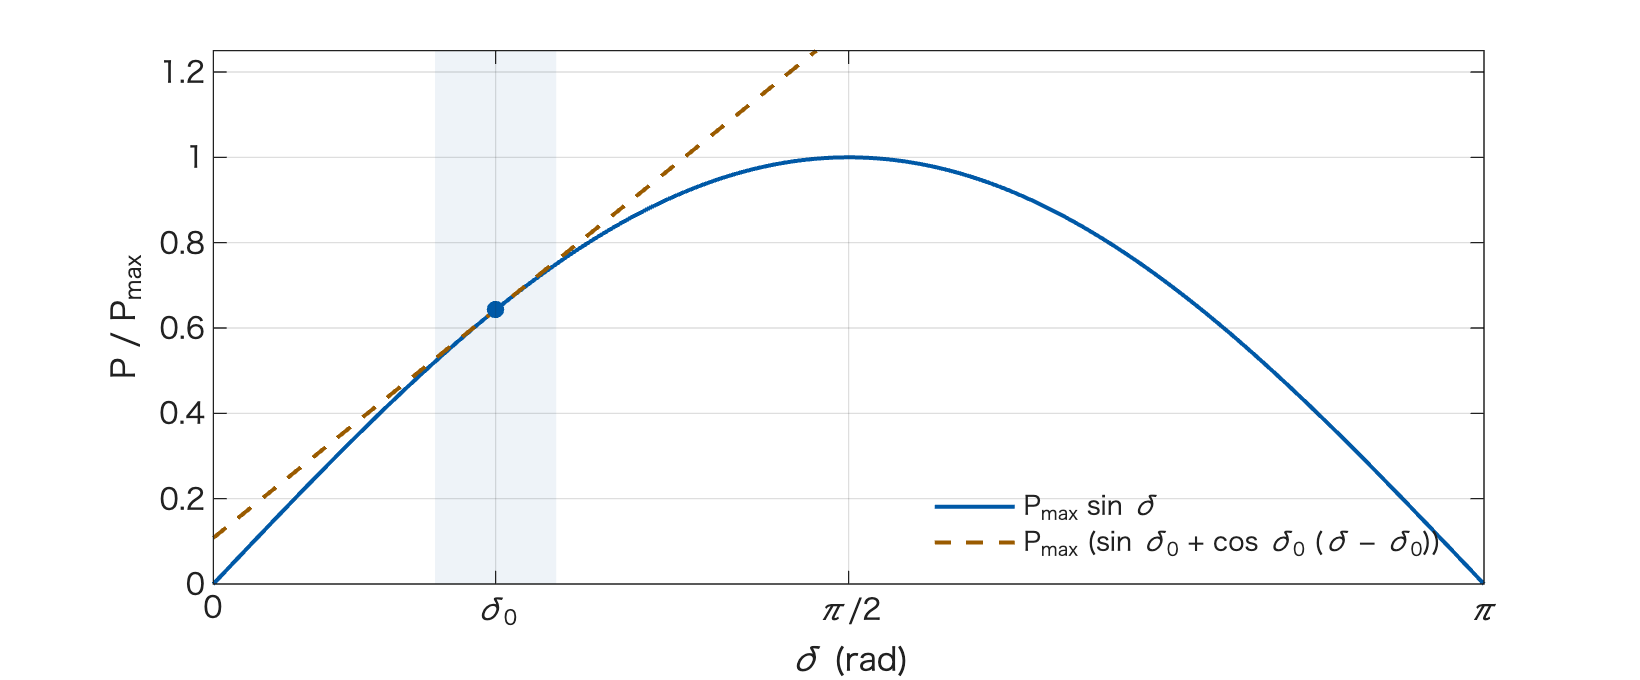

r_delta0 = deg2rad(40);      % 運転点 [rad]
r_band = 0.15;               % 小さな揺れの範囲の半分の幅 [rad]
rv_delta = linspace(0, pi, 400);
c_blue = [0 89 167] / 255;   % 図の色（知識ページの図と同じ）
c_orange = [154 91 0] / 255;
c_green = [46 107 63] / 255;
c_gray = [90 101 112] / 255;
c_tint = [238 243 248] / 255;

figure(Position=[100 100 820 340]);
ax = axes; hold(ax, "on");
patch(ax, r_delta0 + r_band * [-1, 1, 1, -1], [0, 0, 1.25, 1.25], c_tint, EdgeColor="none", HandleVisibility="off");
plot(ax, rv_delta, sin(rv_delta), Color=c_blue, LineWidth=1.5, DisplayName="P_{max} sin \delta");
plot(ax, rv_delta, sin(r_delta0) + cos(r_delta0) * (rv_delta - r_delta0), "--", Color=c_orange, LineWidth=1.5, ...
    DisplayName="P_{max} (sin \delta_0 + cos \delta_0 (\delta − \delta_0))");
plot(ax, r_delta0, sin(r_delta0), "o", MarkerSize=6, MarkerFaceColor=c_blue, Color=c_blue, HandleVisibility="off");
set(ax, XLim=[0, pi], YLim=[0, 1.25], XTick=[0, r_delta0, pi/2, pi], XTickLabel=["0", "\delta_0", "\pi/2", "\pi"], ...
    XGrid="on", YGrid="on", Box="on", Layer="top");
xlabel(ax, "\delta (rad)"); ylabel(ax, "P / P_{max}");
legend(ax, Location="southeast", Box="off");

色を付けた範囲での、曲線と接線の差の最大を計算します。

rv_in = linspace(r_delta0 - r_band, r_delta0 + r_band, 101);
r_err = max(abs(sin(rv_in) - (sin(r_delta0) + cos(r_delta0) * (rv_in - r_delta0))));
fprintf("差の最大: %.4f × Pmax、2 次の項 sin(δ0)Δδ^2/2: %.4f × Pmax\n", r_err, sin(r_delta0) * r_band^2 / 2)

差の最大: 0.0076 × Pmax、2 次の項 sin(δ0)Δδ^2/2: 0.0072 × Pmax


差は $P_\mathrm{max}$ の 0.8% 未満で、テイラー展開の 2 次の項 $\sin\delta_0\,\Delta\delta^2/2$ とほぼ同じ大きさです。$\delta_0$ から離れるほど接線は曲線から外れ、たとえば $\pi/2$ を越えると傾きの符号まで違ってきます。**線形モデルはこの接線を使うので、小さな揺れでしか正確ではありません。**

同じことを、モデルのすべての式についてまとめて行います。系統の状態（回転子の角度、回転の速さ、内部電圧、制御器の状態など）をベクトル $x$ で表し、その式を $\dot{x} = f(x)$ と書きます。運転点 $x_0$ では何も動かないので $f(x_0) = 0$ です。ずれ $\Delta x = x - x_0$ について、$f$ を $x_0$ のまわりでテイラー展開すると次のようになります。


$$\Delta\dot{x} = A\,\Delta x + O\bigl(\|\Delta x\|^{2}\bigr), \qquad A = \left.\frac{\partial f}{\partial x}\right|_{x = x_0}$$


線形モデルは最初の項 $\Delta\dot{x} = A\,\Delta x$ だけを残し、2 次以上の残りを捨てます。$A$ の各要素は、運転点での「ある式の、ある状態に対する傾き」で、このような偏微分を並べた行列をヤコビアンといいます。$A$ は $x_0$ で計算するので、運転点が変われば $A$ も変わります。

## 2. 状態空間モデル

外から加えられる量と測れる量も含めるために、線形モデルを**状態空間モデル**の形に書きます。入力 $u$ は外から変えられる量（電圧の目標値や機械入力など）、出力 $y$ は観測する量（電圧や回転の速さなど）です。


$$\dot{x} = A x + B u, \qquad y = C x + D u$$


ここでの $x$、$u$、$y$ はすべて運転点からのずれです（慣例どおり $\Delta$ を省いています）。$A$（状態行列）は状態どうしの引っぱり合いで、安定かどうかは $A$ だけで決まります。$B$ は入力がどの状態をどれくらい動かすか、$C$、$D$ は測る量を状態と入力からどう作るかです。

電力系統には、各母線での電流のつり合いのように時間微分を含まない式もあります。GUILDA はこれも含めて、状態 $x$、母線電圧 $v$（実部と虚部）、入力 $u$ について次のように線形化します。


$$E\,\dot{x} = A_{xx}\,x + A_{xv}\,v + B_x\,u$$



$$0 = A_{vx}\,x + A_{vv}\,v + B_v\,u$$


2 つ目の式が母線の電流のつり合いです。これを $v$ について解いて（$A_{vv}$ は正則）1 つ目に代入したものが、`get_sys` が既定で返すモデル（Type `"ODE"`）です。


$$E\,\dot{x} = \bigl(A_{xx} - A_{xv} A_{vv}^{-1} A_{vx}\bigr)\,x + \bigl(B_x - A_{xv} A_{vv}^{-1} B_v\bigr)\,u$$


同梱の IEEE 9 母線系統（AVR・PSS 付きの発電機 3 台）を読み込み、潮流計算から平衡点（運転点）を求めて、`get_sys` で線形化します。結果は `ResultLIN` オブジェクトです。

net = network.IEEE9bus(LocalController=true);
[~, flag_init] = net.initialize();
[sys, flag_lin] = net.get_sys();
[flag_init, flag_lin]

ans =      1     1


sys

sys =   ResultLIN のプロパティ:

    tab_variable: [72×8 table]
        rv_point: [72×1 double]
          rm_Axx: [27×27 double]
          rm_Axv: [27×18 double]
           rm_Bx: [27×12 double]
          rm_Avx: [18×27 double]
          rm_Avv: [18×18 double]
           rm_Bv: [18×12 double]
            rm_E: [27×27 double]
            Type: "ODE"
               A: [27×27 double]
               B: [27×12 double]
               C: [27×27 double]
               D: [27×12 double]
               E: [27×27 double]
       StateName: [27×1 string]
       InputName: [12×1 string]
      OutputName: [27×1 string]
            flag: 1
          output: [1×1 struct]
         options: [1×1 struct]
        s_solver: "SolverLIN"
       r_elapsed: 2.2531
       s_network: "PowerNetwork"
       l_success: 1


`A`〜`E` が線形モデル $E\dot{x} = Ax + Bu,\ y = Cx + Du$ の行列で、`StateName`・`InputName` が状態と入力の名前です。`rm_` で始まるのは、母線電圧を消去する前のヤコビアンのブロック（$A_{xx}$ など）です。上の表示に、行列の大きさも出ています。

- `A`（27×27）: 状態どうしの引っぱり合い

- `B`（27×12）: 入力の効き方

- `C`（27×27）、`D`（27×12）: 何を測るか（既定では状態そのもの）と、入力から出力への直通

- `E`（27×27）: 状態方程式の左辺の係数（対角）

状態の名前を見ます。

sys.StateName'

ans = 1×27 の string 配列
    "delta_B001SG1"    "omega_B001SG1"    "Eq_B001SG1"    "Vtr_B001SG1CA1"    "Vap_B001SG1CA1"    "Vst_B001SG1CA1"    "xiWS_B001SG1CP2"    "xi1_B001SG1CP2"    "xi2_B001SG1CP2"    "delta_B002SG1"    "omega_B002SG1"    "Eq_B002SG1"    "Vtr_B002SG1CA1"    "Vap_B002SG1CA1"    "Vst_B002SG1CA1"    "xiWS_B002SG1CP2"    "xi1_B002SG1CP2"    "xi2_B002SG1CP2"    "delta_B003SG1"    "omega_B003SG1"    "Eq_B003SG1"    "Vtr_B003SG1CA1"    "Vap_B003SG1CA1"    "Vst_B003SG1CA1"    "xiWS_B003SG1CP2"    "xi1_B003SG1CP2"    "xi2_B003SG1CP2"


状態は 27 個（発電機 1 台あたり、発電機 3・AVR 3・PSS 3）、入力は 12 個です。名前の後ろは持ち主（`B001SG1` は母線 1 の発電機、`CA1` はその AVR、`CP2` はその PSS）です。$A$ のどこに 0 でない値があるかを描くと、発電機ごとのまとまり（対角のブロック）と、送電線を通した発電機どうしのつながり（ブロックの外）が見えます。

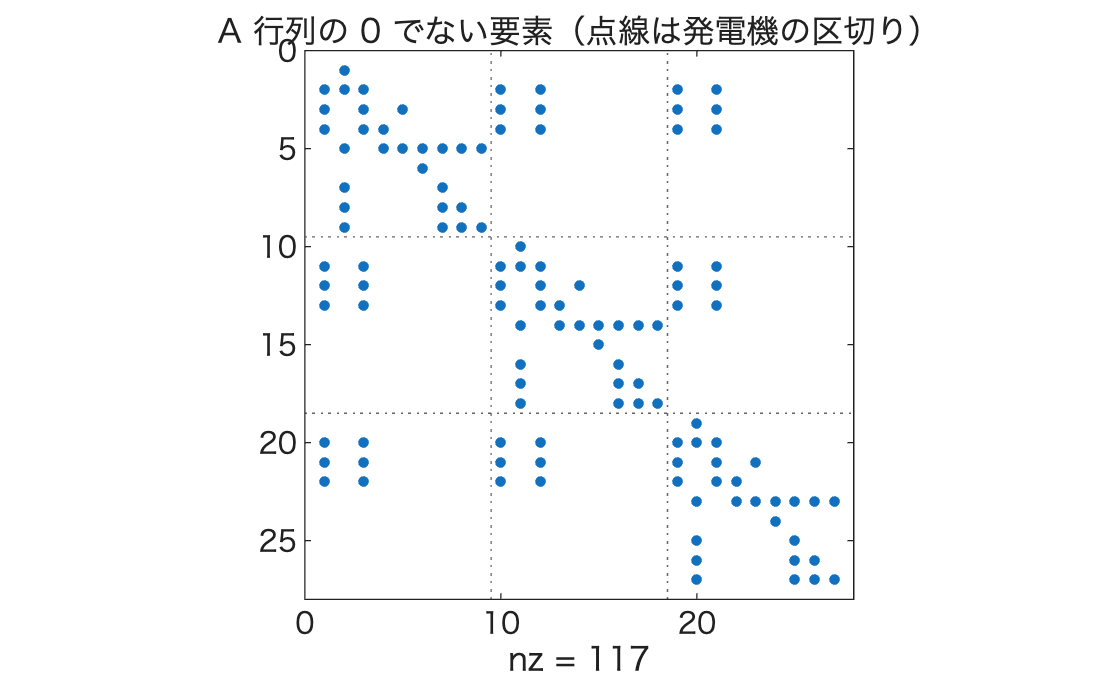

figure
spy(sys.A, 12)
hold on
xline([9.5 18.5], ":"); yline([9.5 18.5], ":")
hold off
title("A 行列の 0 でない要素（点線は発電機の区切り）")

ブロックの外の要素は、主に回転子の角度 `delta` の列にあります。ある発電機の角度が動くと、送電線（ばね）を通してほかの発電機の電気出力が変わるからです。

$E$ は対角行列で、その 0 の行も代数方程式です（AVR や PSS の内部の変数の一部）。そのため固有値は $\det(\lambda E - A) = 0$ の有限な解で、MATLAB では `eig(A, E)` で求まります（無限大の解は捨てます）。

**注意**: `sys.Type = "DAE";` とすると、母線電圧を代数変数として残した形に `A`〜`E` がまとめて切り替わります。平衡点以外の点で線形化するには `net.get_sys(point)` に状態の値を渡します。

## 3. 固有値は揺れの型

小さな外乱のあとの線形モデルの動きは、**モード**と呼ばれるいくつかの単純な動きの重ね合わせになります。モードは $A$ の固有値 $\lambda_i$ に 1 つずつ対応します。$A$ の固有値がすべて異なるとき、ずれ $\Delta x(0)$ から始まる $\Delta\dot{x} = A\,\Delta x$ の解は次のとおりです。


$$\Delta x(t) = \sum_i v_i\, e^{\lambda_i t}\, w_i^{\top} \Delta x(0)$$



$$A v_i = \lambda_i v_i, \qquad w_i^{\top} A = \lambda_i w_i^{\top}, \qquad w_i^{\top} v_i = 1$$


右固有ベクトル $v_i$ はそのモードでどの状態がどう動くかを、左固有ベクトル $w_i$ を使った数 $w_i^{\top}\Delta x(0)$ は外乱がそのモードをどれだけ強く励起するかを表します。固有値は一般に複素数 $\lambda = \sigma \pm j\omega$ で、その対の 2 つの項を合わせると、各状態で $e^{\sigma t}\cos(\omega t + \varphi)$ の実数の振動になります。**実部** $\sigma$ **は揺れが収まるか大きくなるかを、虚部** $\omega$ **は振動の速さを表します。**

4 つの例 $\lambda = -0.5$、$-0.3 \pm 2j$、$0.15 \pm 2j$、$0.3$ [1/s] について、複素平面の位置（上、右半面に色）と、そのモードの動き $e^{\sigma t}\cos\omega t$（下、$t = 0$ で 1）を並べます（知識ページの図）。

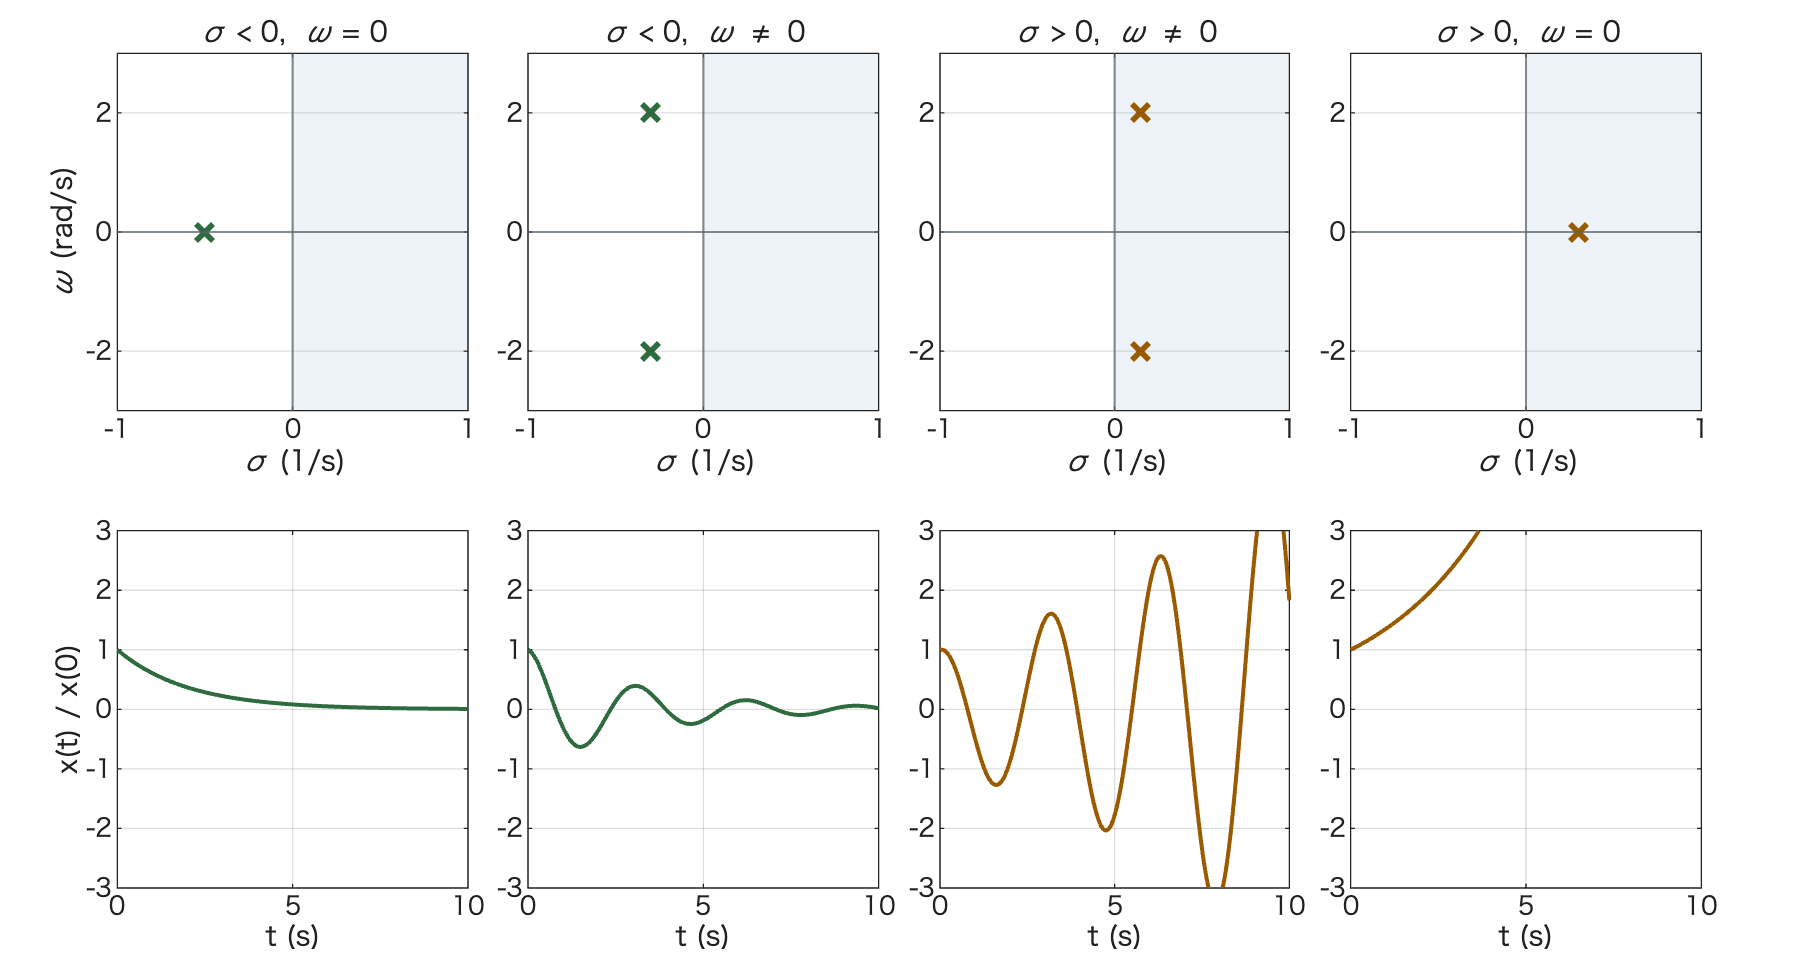

cv_lambda = [-0.5, -0.3 + 2j, 0.15 + 2j, 0.3];    % 各場合の固有値 [1/s]
sr_title = ["\sigma < 0,  \omega = 0", "\sigma < 0,  \omega \neq 0", "\sigma > 0,  \omega \neq 0", "\sigma > 0,  \omega = 0"];
rv_t = linspace(0, 10, 500);
figure(Position=[100 100 900 480]);
layout = tiledlayout(2, 4, TileSpacing="compact", Padding="compact");
for i = 1:4
    c_lambda = cv_lambda(i);
    rr_color = c_green;
    if real(c_lambda) > 0
        rr_color = c_orange;
    end
    ax = nexttile(layout, i); hold(ax, "on");      % 複素平面
    patch(ax, [0, 1, 1, 0], [-3, -3, 3, 3], c_tint, EdgeColor="none");
    xline(ax, 0, Color=c_gray, LineWidth=0.8); yline(ax, 0, Color=c_gray, LineWidth=0.8);
    cv_pair = unique([c_lambda, conj(c_lambda)]);
    plot(ax, real(cv_pair), imag(cv_pair), "x", Color=rr_color, MarkerSize=9, LineWidth=2);
    set(ax, XLim=[-1, 1], YLim=[-3, 3], XTick=[-1, 0, 1], YTick=[-2, 0, 2], XGrid="on", YGrid="on", Box="on", Layer="top");
    title(ax, sr_title(i), FontWeight="normal"); xlabel(ax, "\sigma (1/s)");
    if i == 1, ylabel(ax, "\omega (rad/s)"); end
    ax = nexttile(layout, 4 + i);                   % モードの動き
    plot(ax, rv_t, exp(real(c_lambda) * rv_t) .* cos(imag(c_lambda) * rv_t), Color=rr_color, LineWidth=1.5);
    set(ax, XLim=rv_t([1, end]), YLim=[-3, 3], XGrid="on", YGrid="on", Box="on");
    xlabel(ax, "t (s)");
    if i == 1, ylabel(ax, "x(t) / x(0)"); end
end

虚軸より左（$\sigma \< 0$）なら揺れは収まり、右（$\sigma \> 0$）なら大きくなります。実軸から離れた対（$\omega \neq 0$）は振動し、実軸の上（$\omega = 0$）は振動せずに単調に動きます。

これから、**小信号安定度**（定態安定度）の判定が出てきます。$A$ のすべての固有値の実部が負、つまりすべての固有値が虚軸より左にあれば、その運転点は小さな外乱に対して安定です。

## 4. 複素平面の読み方とダンピング比

すべての固有値を複素平面に描くと、系統の揺れの地図になります。`plot_eigenvalue` で IEEE 9 母線系統の固有値を描きます（虚軸より右の不安定な固有値があれば赤で描かれます）。

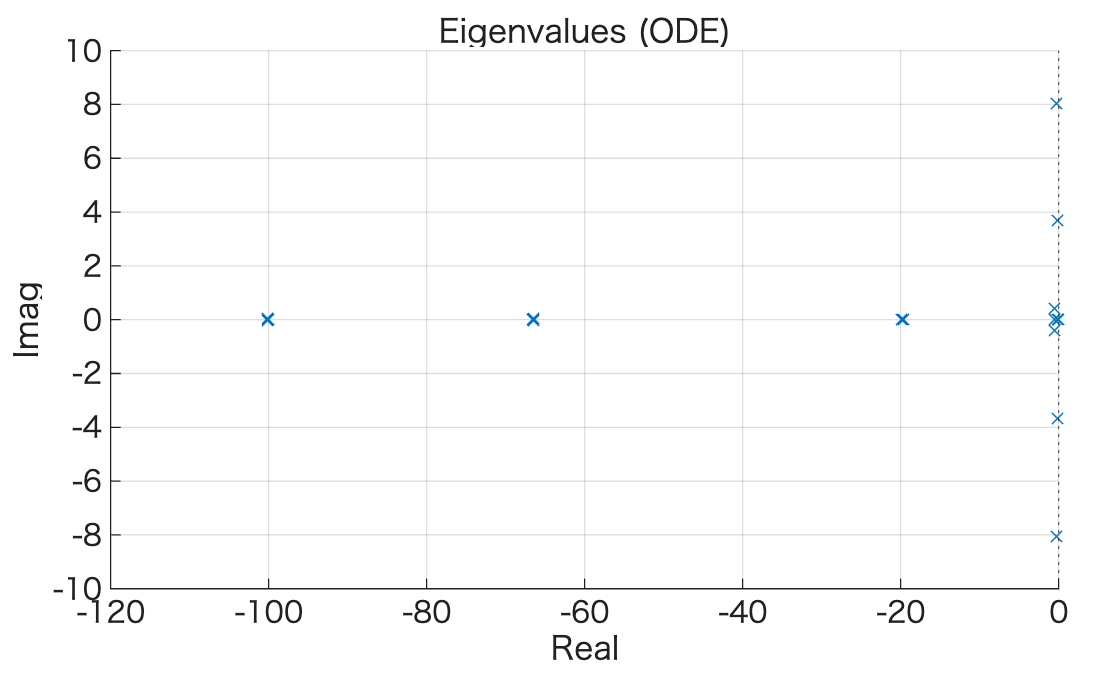

G = sys.plot_eigenvalue();

すべての固有値が虚軸より左にあるので、この運転点は小信号安定です。左のほうにある速い固有値はすぐに減衰するので、気になるのは虚軸の近くです。振動する対 $\lambda = \sigma \pm j\omega$ からは、振動の周波数 $f$ と、振動の速さに比べて揺れがどれだけ早く収まるかを表す**ダンピング比**（減衰比）$\zeta$ を読み取ります。


$$f = \frac{\omega}{2\pi}, \qquad \zeta = \frac{-\sigma}{\sqrt{\sigma^2 + \omega^2}}$$


上にある固有値ほど速く振動します。ダンピング比は原点から見た角度で、原点を通る同じ直線の上にある固有値は $\zeta$ が同じです。1 周期 $2\pi/\omega$ の間に振幅は $e^{2\pi\sigma/\omega}$ 倍になるので、$\zeta$ を使って書くと次のようになります。

for r_zeta = [0.05, 0.10, 0.20]
    fprintf("ζ = %.2f: 1 周期後の振幅の比 %.3f\n", r_zeta, exp(-2 * pi * r_zeta / sqrt(1 - r_zeta^2)));
end

ζ = 0.05: 1 周期後の振幅の比 0.730
ζ = 0.10: 1 周期後の振幅の比 0.532
ζ = 0.20: 1 周期後の振幅の比 0.277


$\zeta = 5\%$ では 1 周期たっても振幅は最初の約 73% 残り、$\zeta = 20\%$ なら約 28% になります。$\zeta$ の小さいモードは長く揺れ続けるので、運用ではすべてのモードに一定以上のダンピング比（たとえば数 %）を求めることがあります。値は系統や運用者によって異なります。

固有値の一覧は `get_mode` で表として受け取れます。1 行が 1 つのモード（複素数の対は虚部が正のほうだけ）で、固有値 `Eigenvalue`、周波数 `Frequency` [Hz]、ダンピング比 `DampingRatio`、そのモードへの参加が最も大きい状態の持ち主 `Owner` が並びます。行は実部の大きい順（減衰しにくい順）です。$E$ の 0 の行から出る無限大の固有値は、モードではないので入りません。

[tab_mode, sct_mode] = sys.get_mode()

tab_mode = 16×4 table
         Eigenvalue          Frequency    DampingRatio       Owner    
    _____________________    _________    ____________    ____________

    -2.9315e-13+0i                   0           NaN      "B002SG1"   
     -0.0069046+0i                   0           NaN      "B002SG1CP2"
       -0.10078+0i                   0           NaN      "B001SG1CP2"
       -0.10217+0i                   0           NaN      "B003SG1CP2"
       -0.15023+3.6739i        0.58471      0.040858      "B002SG1"   
        -0.1716+0i                   0           NaN      "B003SG1"   
       -0.32656+8.0476i         1.2808      0.040546      "B003SG1"   
       -0.48189+0i                   0           NaN      "B001SG1"   
       -0.52661+0.41808i       0.06654       0.78319      "B001SG1"   
        -19.617+0i                   0           NaN      "B001SG1CA1"
        -19.909+0i                   0           NaN      "B001SG1CA1"
         -19.93+0i                   0           NaN  

sct_mode = フィールドをもつ struct:
    rm_participation: [27×16 double]
            cm_shape: [27×16 double]
            sv_state: [27×1 string]
            sv_owner: [27×1 string]
              s_type: "ODE"


原点の近くを拡大し、ダンピング比 5% と 10% の線を加えます。最も周波数の高い 2 対の振動する固有値に、周波数とダンピング比を書き込みます（知識ページの図）。

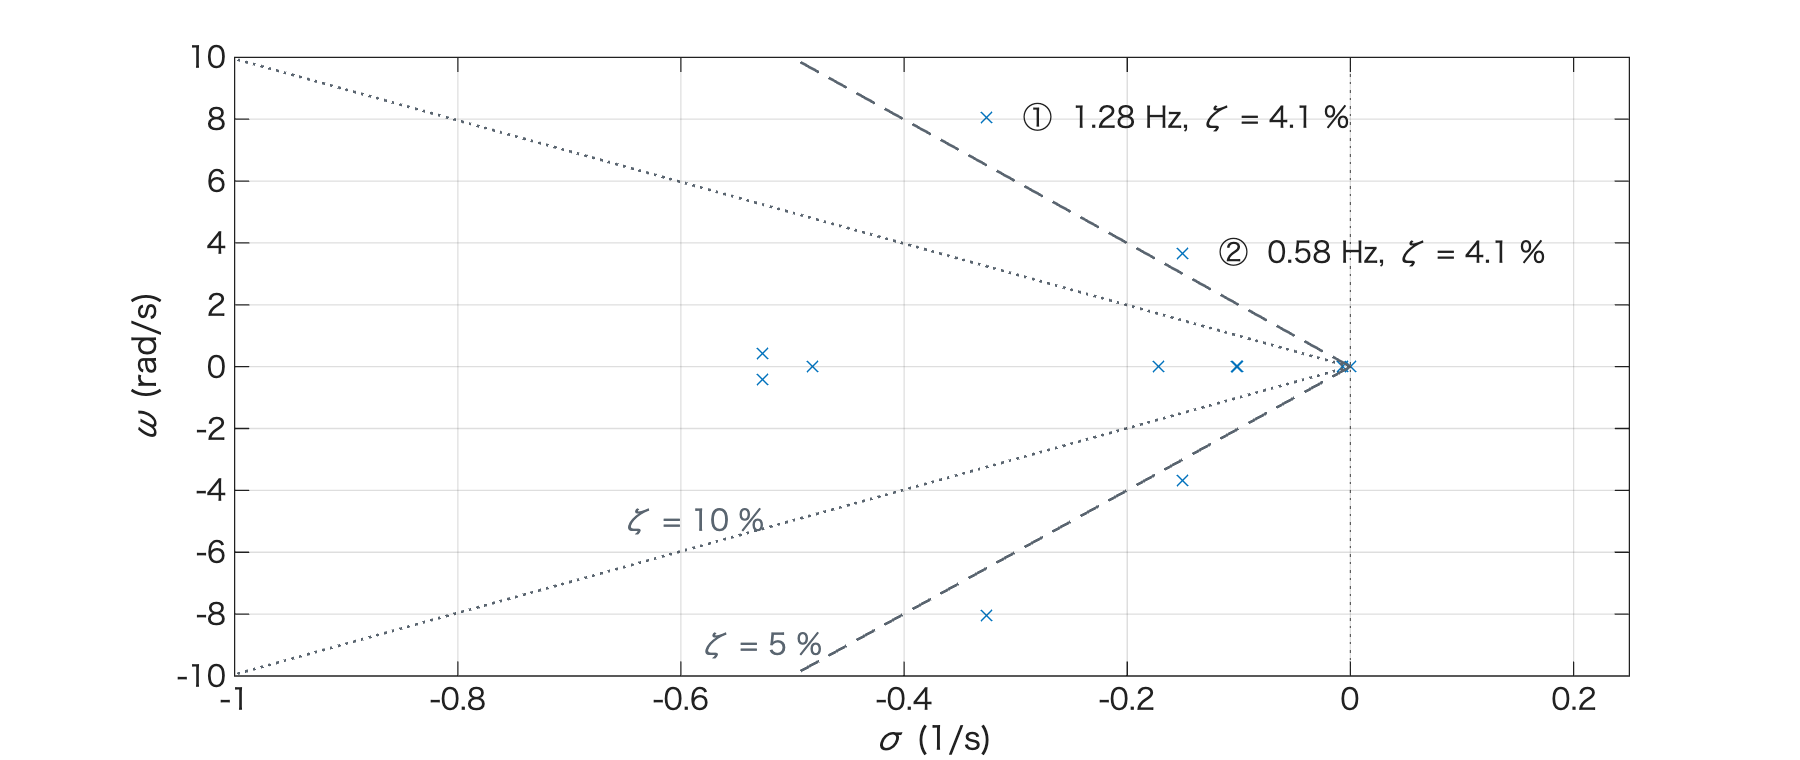

[~, iv_em] = maxk(tab_mode.Frequency, 2);  % モード ① と ② の行
cv_em = tab_mode.Eigenvalue(iv_em);

figure(Position=[100 100 900 380]);
ax = axes;
sys.plot_eigenvalue(Parent=ax);
hold(ax, "on");
rr_zeta = [0.05, 0.10];
rr_wlabel = [-9, -5];                       % 線の名前を書く高さ [rad/s]
rv_w = linspace(0, 10, 2);
sr_style = ["--", ":"];
for i = 1:2
    rv_s = -rr_zeta(i) / sqrt(1 - rr_zeta(i)^2) * rv_w;     % ダンピング比 ζ の直線
    plot(ax, [rv_s, NaN, rv_s], [rv_w, NaN, -rv_w], sr_style(i), Color=c_gray, LineWidth=1);
    text(ax, -rr_zeta(i) / sqrt(1 - rr_zeta(i)^2) * abs(rr_wlabel(i)) - 0.02, rr_wlabel(i), ...
        sprintf("\\zeta = %d %%", round(100 * rr_zeta(i))), Color=c_gray, HorizontalAlignment="right");
end
sr_mark = ["①", "②"];
for i = 1:2
    c = cv_em(i);
    text(ax, real(c) + 0.03, imag(c), sprintf("%s  %.2f Hz, \\zeta = %.1f %%", sr_mark(i), imag(c) / (2*pi), -100 * real(c) / abs(c)), ...
        VerticalAlignment="middle");
end
set(ax, XLim=[-1, 0.25], YLim=[-10, 10], XGrid="on", YGrid="on", Box="on", Layer="top");
legend(ax, "off"); title(ax, "");
xlabel(ax, "\sigma (1/s)"); ylabel(ax, "\omega (rad/s)");

① と ② は 2 対の**電気機械モード**（発電機の回転子どうしの揺れ）で、どちらもダンピング比は約 4.1% と、5% の線のすぐ内側にあります。ほかの固有値は実数か、よく減衰しています。振動するモードだけを取り出すには、`MinFrequency` を指定します（0.05 Hz 以上）。

sys.get_mode(MinFrequency=0.05)

ans = 3×4 table
       Eigenvalue        Frequency    DampingRatio      Owner  
    _________________    _________    ____________    _________

    -0.15023+3.6739i      0.58471       0.040858      "B002SG1"
    -0.32656+8.0476i       1.2808       0.040546      "B003SG1"
    -0.52661+0.41808i     0.06654        0.78319      "B001SG1"


上の 2 つ（1.28 Hz と 0.58 Hz）がモード ① と ② で、この系統で最も減衰しにくいモードです。3 つ目の 0.07 Hz ほどのモードはダンピング比が 80% 近くあり、ほとんど振動せずに収まります。

最も原点に近い固有値の大きさも確かめておきます（`tab_mode` の 1 行目です）。

min(abs(tab_mode.Eigenvalue))

ans = 2.9315e-13

原点のごく近く（数値誤差の大きさ）に固有値が 1 つあります。これは揺れではありません。すべての回転子の角度を同じだけ回す動きに対応し、効くのは角度の差だけなので、運転状態は変わりません（Part 4 の「絵全体を回してもつり合いは変わらない」と同じ理由です）。

## 5. 振動モードの種類とモード形

電力系統の振動モードの多くは、ばねでつながれた重りのように互いに揺れ合う発電機の回転子から生まれます。この電気機械モードは、どの発電機がどの発電機に対して揺れるかで名前が付いています。

- **局所モード**: 1 台の発電機（または 1 つの発電所）が、近くの系統の残りに対して揺れます。目安は 1〜2 Hz 程度です。

- **地域間モード**: ある地域の発電機の群れ全体が、長い連系線を通して別の地域の群れに対して揺れます。より遅く、目安は 0.1〜0.7 Hz 程度で、減衰が小さくなりやすいモードです。

- **制御モード**: 回転子よりも、AVR やガバナなどの制御器から主に生まれるモードです。

どの発電機がどちら向きに揺れるかは、そのモードの右固有ベクトル（**モード形**）から読み取ります。モード形は `get_mode` の 2 番目の出力 `sct_mode.cm_shape`（列が `tab_mode` の行、行が状態）に入っています。モード ① と ② の右固有ベクトル（$Av = \lambda E v$）のうち回転の速さ `omega` の成分を取り出し、その中で最大の成分が 1 になるように割って、実部を棒で描きます（知識ページの図）。

lv_omega = startsWith(sct_mode.sv_state, "omega_");
cm_shape = sct_mode.cm_shape(lv_omega, iv_em);
[~, iv_max] = max(abs(cm_shape), [], 1);
cm_shape = cm_shape ./ cm_shape(sub2ind(size(cm_shape), iv_max, 1:2));    % 最大の成分を 1 にそろえる
max(abs(imag(cm_shape)), [], "all")        % 虚部の大きさ（小さいことを確かめる）

ans = 0.0387

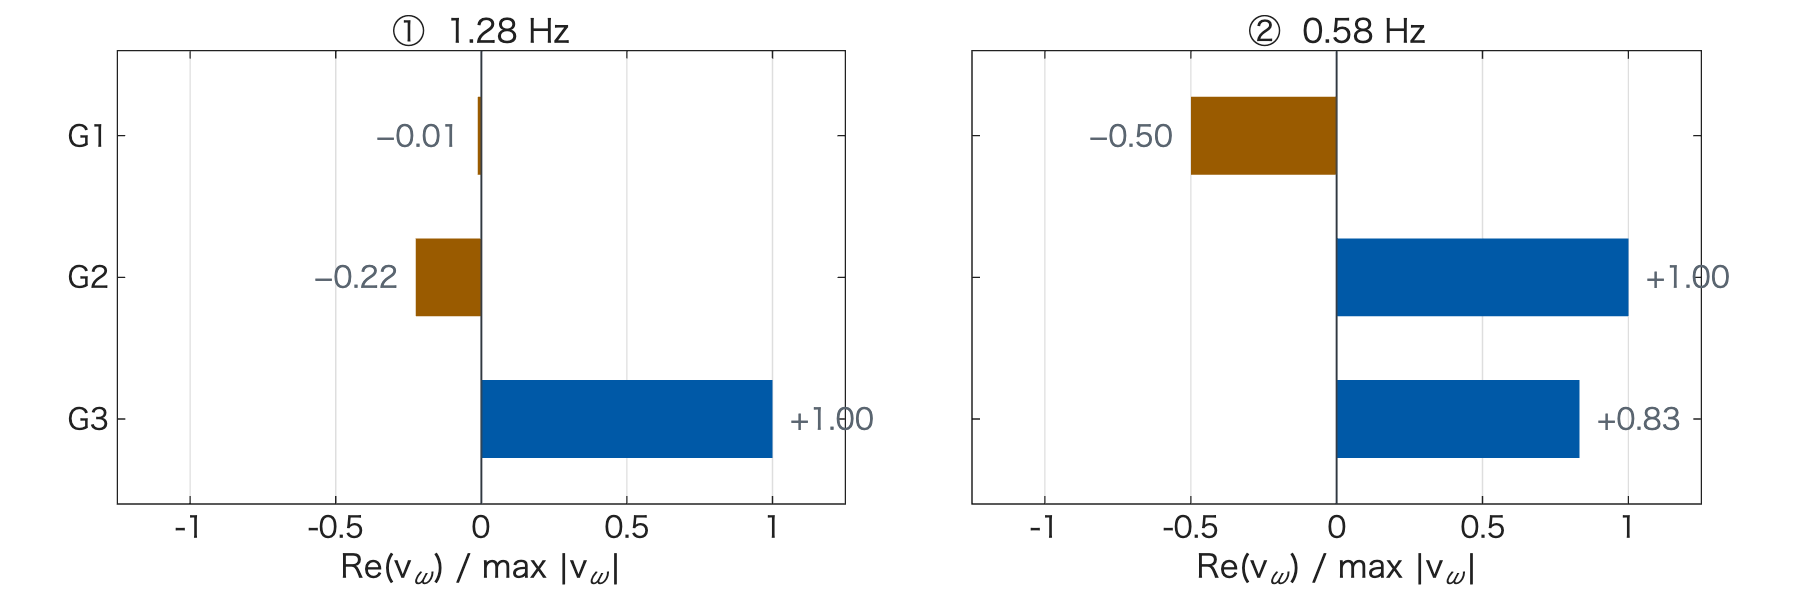


figure(Position=[100 100 900 300]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
for i = 1:2
    ax = nexttile(layout); hold(ax, "on");
    rv_val = real(cm_shape(:, i));
    xline(ax, 0, Color=[0.22 0.26 0.3], LineWidth=0.8);
    b = barh(ax, 1:3, rv_val, 0.55, FaceColor="flat", EdgeColor="none");
    b.CData = repmat(c_blue, 3, 1);
    b.CData(rv_val < 0, :) = repmat(c_orange, nnz(rv_val < 0), 1);
    for k = 1:3
        s_align = "left";
        if rv_val(k) < 0, s_align = "right"; end
        text(ax, rv_val(k) + 0.06 * sign(rv_val(k) + (rv_val(k) == 0)), k, replace(sprintf("%+.2f", rv_val(k)), "-", "−"), ...
            HorizontalAlignment=s_align, Color=c_gray);
    end
    set(ax, XLim=[-1.25, 1.25], YLim=[0.4, 3.6], YDir="reverse", YTick=1:3, YTickLabel=["G1", "G2", "G3"], XGrid="on", Box="on");
    title(ax, sprintf("%s  %.2f Hz", sr_mark(i), tab_mode.Frequency(iv_em(i))));
    xlabel(ax, "Re(v_{\omega}) / max |v_{\omega}|");
    if i == 2, ax.YTickLabel = []; end
end

虚部は 0.04 未満と小さいので、実部の棒で向きを読めます。右向きの棒と左向きの棒は、逆向き（逆位相）に揺れることを表します。

- モード ①（1.28 Hz）は、発電機 3 が発電機 2 に対して揺れ、発電機 1 はほとんど動きません。2 台どうしの速い揺れで、局所モードに近い形です。

- モード ②（0.58 Hz）は、発電機 2 と 3 がそろって発電機 1 に対して揺れます。発電機 1 の棒が短いのは、慣性が大きい（$M = 100$ s、ほかの 5〜8 倍）ので、同じ力でも速さがあまり変わらないからです。大きな系統では、このような群れどうしの揺れが地域間モードになります。

周波数の違いも、Part 3 の $\omega_\mathrm{n} = \sqrt{2\pi f_0 K_\mathrm{s}/M}$ で説明できます。軽い 2 台が互いに揺れる ① は速く、重い発電機 1 を相手にする ② は遅くなります。

## 6. 参加係数

モード形は、そのモードで状態がどう動くかを表します。これと関係する問いが、どの状態がそのモードをつくっているか、つまり系統のどこを変えるとそのモードが変わるか、です。これに答えるのが**参加係数**で、右固有ベクトル $v_i$（状態がモードでどう動くか）と左固有ベクトル $w_i$（状態がモードをどれだけ励起するか）を成分ごとに掛け合わせます。


$$p_{ki} = \frac{|w_{ki}\, v_{ki}|}{\sum_{j} |w_{ji}\, v_{ji}|}$$


$v_{ki}$ と $w_{ki}$ は、モード $i$ の右固有ベクトルと左固有ベクトルの状態 $k$ の成分で、$p_{ki}$ はモード $i$ に対する状態 $k$ の割合です。1 つのモードについて合計すると 1 になります。積 $w_{ki}v_{ki}$ は状態を別の単位で測っても変わらないので、別の発電機や制御器の状態どうしをそのまま比べられます。

GUILDA のモデルは $E\dot{x} = Ax$ の形なので、`get_mode` は右固有ベクトルに $E$ を掛けた積 $|w_{ki}(Ev_i)_k|$ を、モードごとに合計 1 にそろえて参加係数とします。$E$ の対角の 0 の行（代数方程式）は参加 0 になり、残りは代数方程式を消去した $\dot{x} = A_\mathrm{r}x$ の形で上の式を使った値と同じです（$A_\mathrm{r}$ は 7 節）。参加係数は `sct_mode.rm_participation`（行が状態、列が `tab_mode` の行）に入っています。

rm_P = sct_mode.rm_participation(:, iv_em);   % モード ① と ② の参加係数

状態ごとの参加係数を、発電機ごと（その AVR・PSS の状態も含めて）に合計して描きます（知識ページの図）。状態の持ち主 `sct_mode.sv_owner` は、発電機のタグか、その制御器のタグ（`B001SG1CA1` のように発電機のタグで始まる）です。

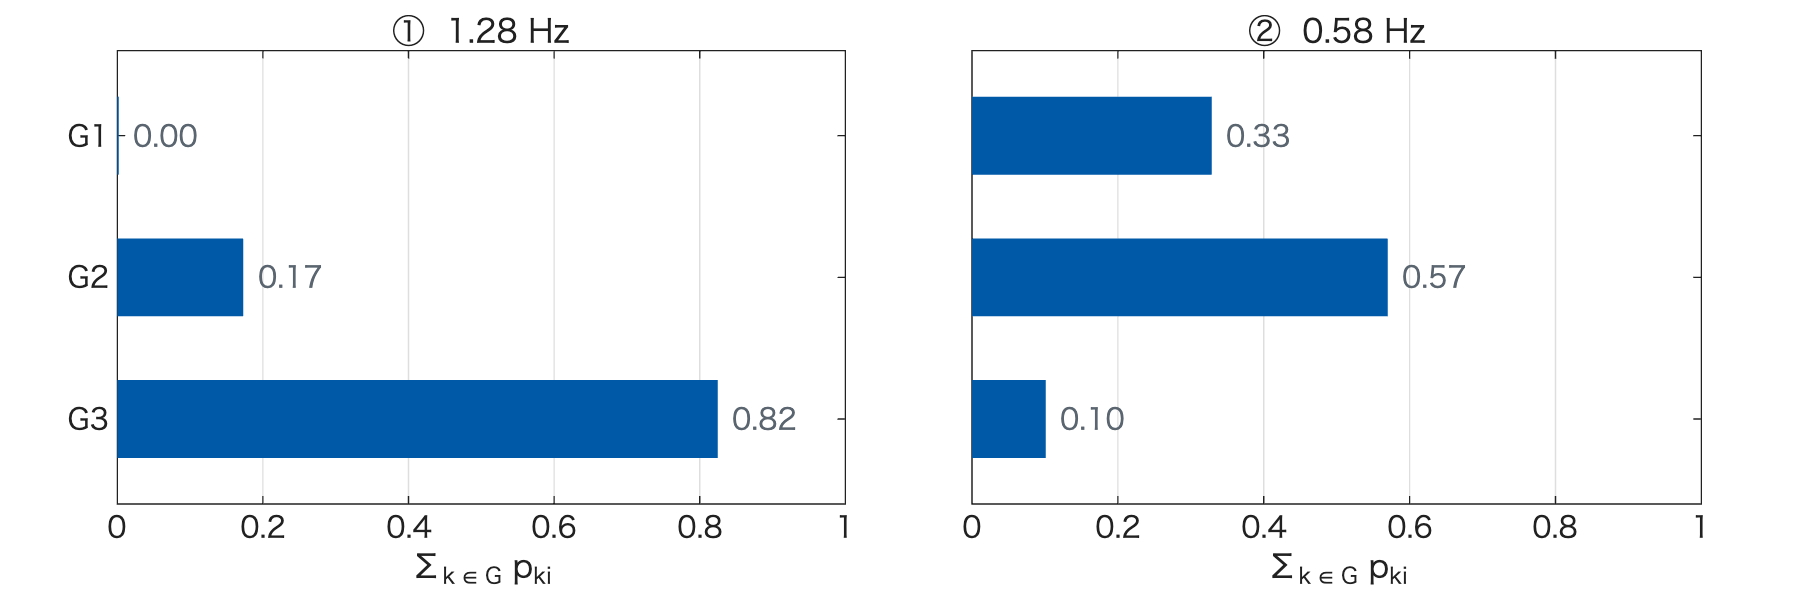

sr_gen = ["B001SG1", "B002SG1", "B003SG1"];
rm_Pgen = zeros(3, 2);
for k = 1:3
    rm_Pgen(k, :) = sum(rm_P(startsWith(sct_mode.sv_owner, sr_gen(k)), :), 1);
end
figure(Position=[100 100 900 300]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
for i = 1:2
    ax = nexttile(layout); hold(ax, "on");
    barh(ax, 1:3, rm_Pgen(:, i), 0.55, FaceColor=c_blue, EdgeColor="none");
    for k = 1:3
        text(ax, rm_Pgen(k, i) + 0.02, k, sprintf("%.2f", rm_Pgen(k, i)), Color=c_gray);
    end
    set(ax, XLim=[0, 1], YLim=[0.4, 3.6], YDir="reverse", YTick=1:3, YTickLabel=["G1", "G2", "G3"], XGrid="on", Box="on");
    title(ax, sprintf("%s  %.2f Hz", sr_mark(i), tab_mode.Frequency(iv_em(i))));
    xlabel(ax, "\Sigma_{k \in G} p_{ki}");
    if i == 2, ax.YTickLabel = []; end
end

モード ① はほとんど発電機 3、モード ② は主に発電機 2 と 1 がつくっています。モード形（5 節）と比べると、① で大きく動く発電機 3 が、① をつくっている発電機でもあります。一方 ② では、大きく動く発電機 3（モード形 +0.83）の参加は 0.10 と小さく、発電機 1 の参加が 0.33 と大きく出ます。動きの大きさ（$v$）と、そのモードへの効きやすさ（$w$）は別のものだからです。

状態ごとに見ると、どの状態が効いているかまで分かります。参加の大きい状態を上から 5 つ並べます。

for i = 1:2
    [rv_p, iv_k] = maxk(rm_P(:, i), 5);
    fprintf("モード %s: %s\n", sr_mark(i), join(compose("%s %.2f", sct_mode.sv_state(iv_k), rv_p), ", "));
end

モード ①: omega_B003SG1 0.40, delta_B003SG1 0.40, omega_B002SG1 0.08, delta_B002SG1 0.08, Eq_B003SG1 0.02
モード ②: omega_B002SG1 0.26, delta_B002SG1 0.25, delta_B001SG1 0.15, omega_B001SG1 0.15, Eq_B002SG1 0.05


どちらのモードも、回転子の角度 `delta` と回転の速さ `omega` の参加が大きく、回転子の揺れから生まれたモードであることが分かります。揺れを抑える制御器（PSS）は、抑えたいモードへの参加の大きい発電機に付けると効きやすくなります。発電機の出力、送電線、制御器のゲインなどを変えると $A$ が変わり、固有値も動きます。参加係数は、その動きがどこで大きいかの見当を与えます（Part 6 の定態安定度制約付き OPF は、この感度を使います）。

**注意**: 参加係数の定義には、複素数の積 $w_{ki}v_{ki}$ そのものを使う形と、ここでの絶対値を正規化した形があります。発電機ごとの合計の大小関係は、どちらでもほぼ同じです。`tab_mode.Owner` は、各モードで参加の最も大きい状態の持ち主です。

## 7. 大きな揺れでは合わなくなる

線形モデルは 1 つの運転点での接線なので、系統がその点の近くにいる間しか正確ではありません。発電機 2 の回転子の角度を平衡点から少し（0.05 rad）ずらした場合と、大きく（1.2 rad）ずらした場合について、角度の差 $\delta_2 - \delta_1$ の平衡点からのずれを、線形モデルと時間シミュレーション（非線形）で比べます（知識ページの図）。

- 非線形: 時刻 0 に角度をずらすシナリオ（`add_offset`）の時間シミュレーション。

- 線形: 代数方程式を消去した $\dot{x}_\mathrm{d} = A_\mathrm{r}\,x_\mathrm{d}$ の解 $x_\mathrm{d}(t) = e^{A_\mathrm{r} t}x_\mathrm{d}(0)$（`expm`）。

微分を含む状態を d、含まない状態（$E$ の対角の 0）を a と分けると、2 つ目の組の式 $0 = A_\mathrm{ad}x_\mathrm{d} + A_\mathrm{aa}x_\mathrm{a}$ を $x_\mathrm{a}$ について解いて代入でき、次のようになります（2 節で母線電圧を消去したのと同じ手順です）。


$$A_\mathrm{r} = E_\mathrm{dd}^{-1}\bigl(A_\mathrm{dd} - A_\mathrm{da} A_\mathrm{aa}^{-1} A_\mathrm{ad}\bigr)$$


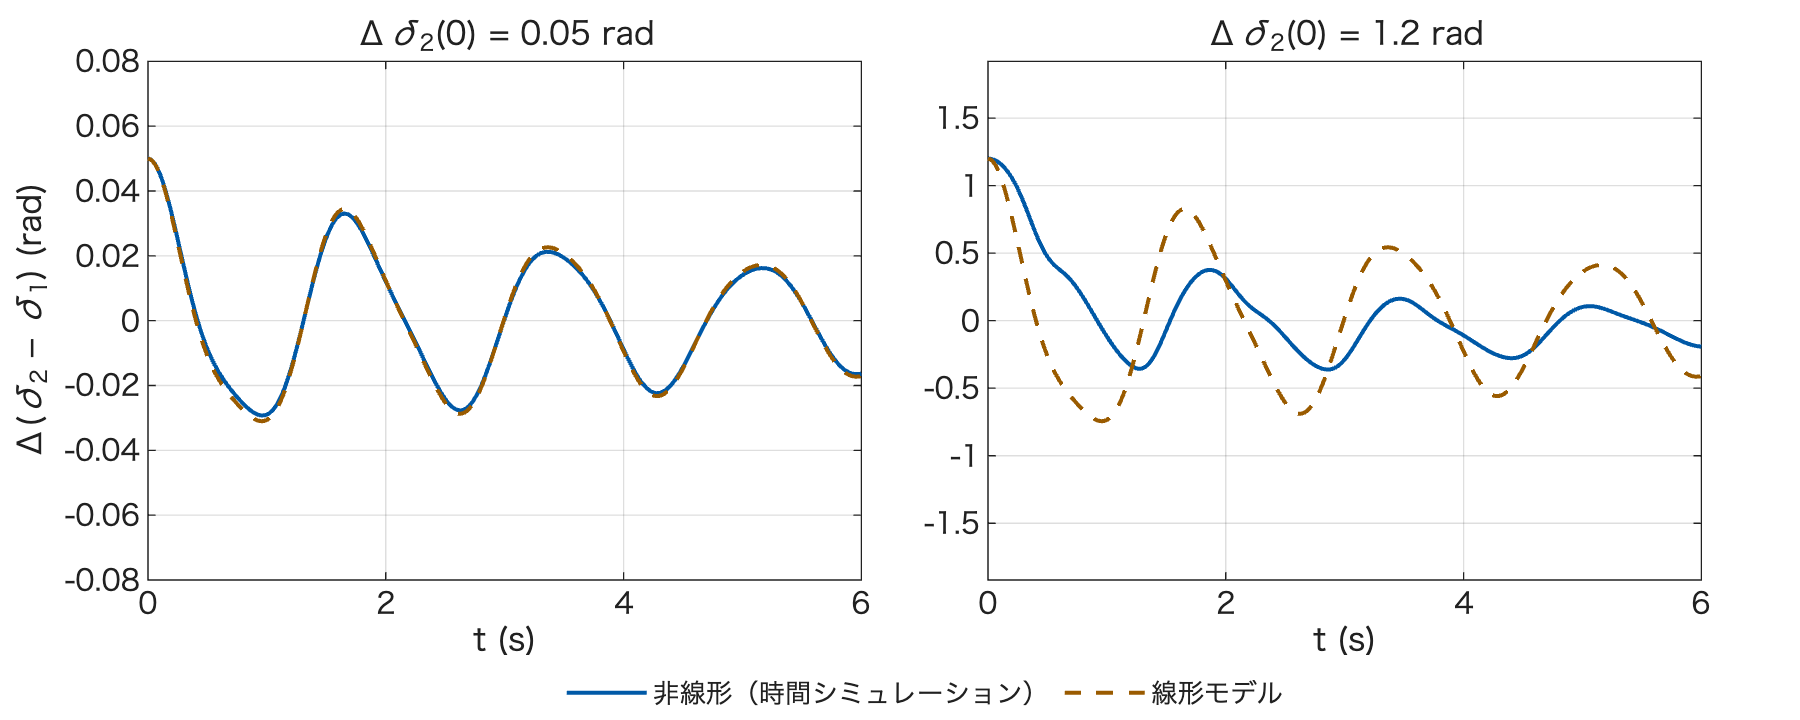

lv_dyn = diag(sys.E) ~= 0;                 % 微分を含む状態
A_red = sys.E(lv_dyn, lv_dyn) \ (sys.A(lv_dyn, lv_dyn) - sys.A(lv_dyn, ~lv_dyn) / sys.A(~lv_dyn, ~lv_dyn) * sys.A(~lv_dyn, lv_dyn));
sv_state = sys.StateName(lv_dyn);
r_d21eq = net.get_element("B002SG1").rv_Xequilibrium(1) - net.get_element("B001SG1").rv_Xequilibrium(1);   % 平衡点の角度の差 [rad]
rr_push = [0.05, 1.2];          % 発電機 2 の角度のずれ [rad]
rv_t = linspace(0, 6, 301);
i_d1 = find(sv_state == "delta_B001SG1");
i_d2 = find(sv_state == "delta_B002SG1");
c_nl = cell(1, 2);
c_lin = cell(1, 2);
for i = 1:2
    s_tag = "push" + i;
    sc = net.add_scenario(s_tag, Time=[0, 6]);
    sc.add_offset("B002SG1", "delta", rr_push(i), 0);
    res = net.simulate(s_tag, Progress="none");
    tab_d = res.get_trajectory("delta");
    c_nl{i} = [tab_d.t, tab_d.B002SG1 - tab_d.B001SG1 - r_d21eq];
    rv_x0 = zeros(size(A_red, 1), 1);
    rv_x0(i_d2) = rr_push(i);
    rv_dd = zeros(size(rv_t));
    for k = 1:numel(rv_t)
        rv_x = real(expm(A_red * rv_t(k)) * rv_x0);
        rv_dd(k) = rv_x(i_d2) - rv_x(i_d1);
    end
    c_lin{i} = [rv_t(:), rv_dd(:)];
end

figure(Position=[100 100 900 360]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
for i = 1:2
    ax = nexttile(layout); hold(ax, "on");
    plot(ax, c_nl{i}(:, 1), c_nl{i}(:, 2), Color=c_blue, LineWidth=1.5, DisplayName="非線形（時間シミュレーション）");
    plot(ax, c_lin{i}(:, 1), c_lin{i}(:, 2), "--", Color=c_orange, LineWidth=1.5, DisplayName="線形モデル");
    r_lim = 1.6 * rr_push(i);
    set(ax, XLim=[0, 6], YLim=[-r_lim, r_lim], XGrid="on", YGrid="on", Box="on");
    title(ax, sprintf("\\Delta\\delta_2(0) = %g rad", rr_push(i)), FontWeight="normal");
    xlabel(ax, "t (s)");
    if i == 1, ylabel(ax, "\Delta(\delta_2 − \delta_1) (rad)"); end
end
lg = legend(nexttile(layout, 1), Orientation="horizontal", Box="off");
lg.Layout.Tile = "south";

小さくずらした場合（左）は、2 本の曲線がほぼ重なります。大きくずらした場合（右）は、線形モデルが実際の（非線形の）系統の 2 倍ほど大きく揺れ、揺れのリズムも違います。1.2 rad（約 69°）もずれると、1 節の図のように接線と $\sin$ の曲線の差が大きくなり、ばねの「硬さ」がずれの大きさで変わってしまうからです。

線形モデルは常に比例して答えます。2 倍ずらせば 2 倍揺れ、安定な線形モデルは決して脱調しません。揺れが大きいときの実際の系統はそうはなりません。地絡などの大きな外乱に耐えられるか（過渡安定度）は、時間シミュレーションで確かめる必要があります（Part 3）。2 つの道具は補い合います。いつも起きている多くの小さな外乱には線形モデル、少数の大きな出来事には時間シミュレーションを使います。

## 8. GUILDA での線形化

GUILDA では、潮流計算や時間シミュレーションと同じ系統モデルから線形モデルを作ります。発電機・負荷・制御器がそれぞれ自分の線形のブロックを出し、GUILDA がそれらを系統を通してつなぎます。運転点は、潮流計算から求めた平衡点です。

- `net.get_sys()` は行列 `A`〜`E` と状態・入力の名前を持つ `ResultLIN` オブジェクトを返します（2 節）。

- `sys.plot_eigenvalue()` は固有値を複素平面に描きます（4 節）。

- `sys.get_ss("ODE")` は、モデルを Control System Toolbox の状態空間（`ss`）オブジェクトとして返します。制御器の設計に使えます（Part 8）。

sys_ss = sys.get_ss("ODE");
size(sys_ss)

27 個の出力、12 個の入力、27 個の状態を持つ状態空間モデル。


max(real(pole(sys_ss)))

ans = 2.9193e-14

`ss` オブジェクトの極（`pole`）は、4 節の固有値と同じです。最大の実部は $10^{-13}$ 程度の数値誤差の大きさで、4 節で見た原点の固有値にあたります。それ以外の極は、すべて虚軸より左にあります。

**注意**: 既定では出力は状態そのもので（$C$ は単位行列）、出力名は空です。母線電圧などを出力にするには `sys.get_ss("ODE", Output="V")` のように指定します。`Format="struct"` なら Toolbox なしで行列を受け取れます。線形モデルは、平衡点以外の点（たとえば時間シミュレーションのある時刻）でも、系統の一部（母線・機器・制御器）についても求められます。

## まとめ

- 運転点のまわりの小さな揺れは、線形モデル $\Delta\dot{x} \approx A\,\Delta x$ で表せます。$A$ はその点でのモデルのヤコビアンで、GUILDA では `net.get_sys()` で求まります。

- $A$ の固有値の 1 つ 1 つが揺れの型です。すべての固有値が虚軸より左にあれば、その運転点は小信号安定です。

- 振動する対 $\sigma \pm j\omega$ からは、周波数 $f = \omega/2\pi$ とダンピング比 $\zeta$ を読み取ります。IEEE 9 母線系統では、1.28 Hz と 0.58 Hz の 2 つの電気機械モードが $\zeta \approx 4\%$ で、最も減衰しにくいモードでした。

- モード形は誰が誰に対して揺れるかを、参加係数はどの状態がそのモードをつくっているかを表します。

- 線形モデルが使えるのは小さな揺れだけです。大きな外乱には時間シミュレーションが必要です。

## 次の Part

Part 6「最適潮流計算と定態安定度制約付き OPF」では、最も安い運転点を求め、その点で線形化した固有値の減衰を保つように運転を選び直します。知識ページ: [Part 6: 最適潮流計算と定態安定度制約付き OPF](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part6-optimal-power-flow.html","-browser"))

[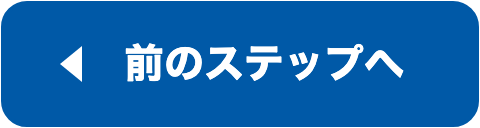](matlab:open('Part4_SpringMassModel.mlx'))　　[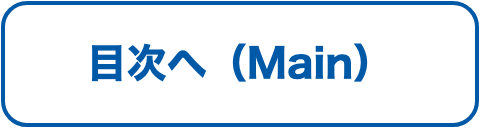](matlab:open('Main.mlx'))　　[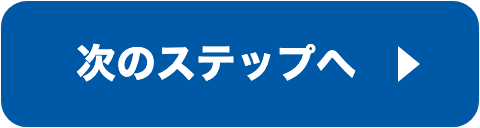](matlab:open('Part6_OptimalPowerFlow.mlx'))